# **两次优化**

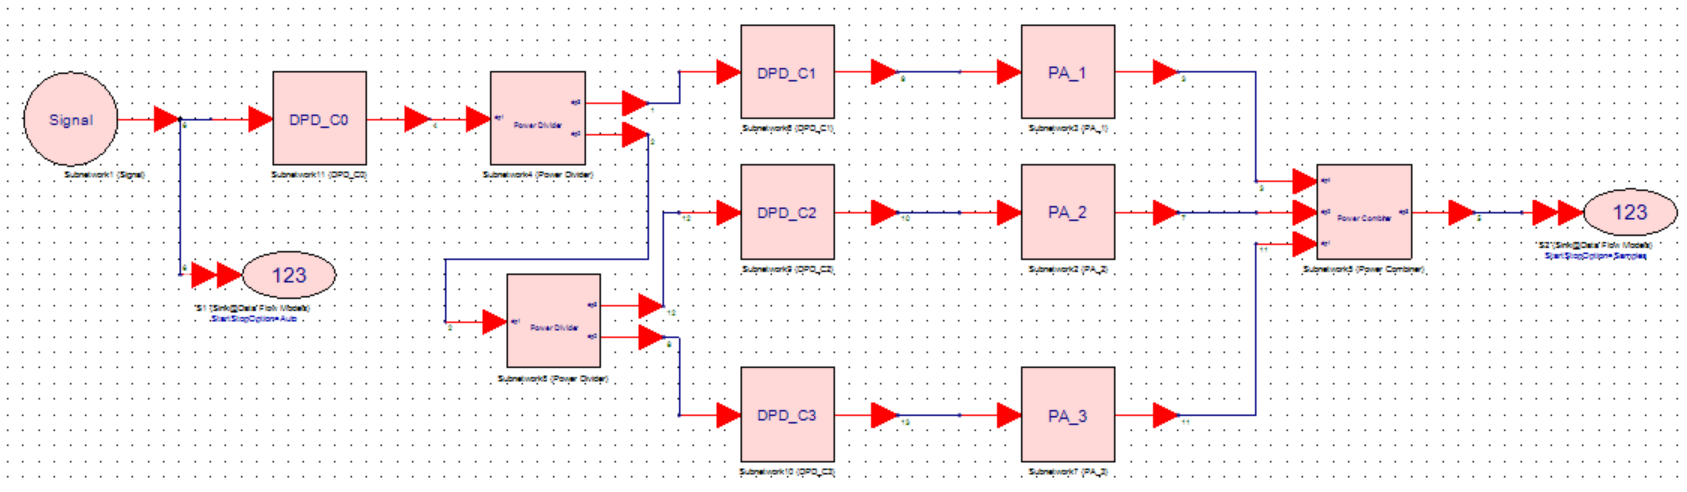

% 运行前请先将子文件夹添加到路径
clc; 

## -----------------------------Model C Train----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Train();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
Sys_output = Data_matrix(:,end-1) + 1i * Data_matrix(:,end); 
% 参数需要保持一致
 M = 4; 

## 【训练】整体优化

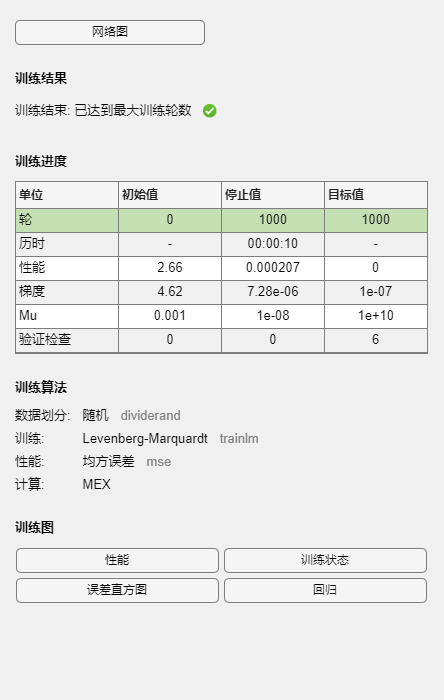

% 训练整体
net = feedforwardnet(5); 
[model_input,model_output] = pre_train(M,real(Sys_input),imag(Sys_input),real(Sys_output),imag(Sys_output),dim);
model = train(net, model_input, model_output);

save('Method_C\Whole\FNN.mat', 'model');

## 第一次迭代

% 系统仿真
Sys_input_DPD=DPD(Sys_input,M,'Method_C\Whole\FNN.mat'); % DPD
[PA1_input,A23] = Power_Divider(Sys_input_DPD);
[PA2_input,PA3_input] = Power_Divider(A23);
PA1_output = PA_1(PA1_input);
PA2_output = PA_2(PA2_input);
PA3_output = PA_3(PA3_input);
% 取参数

## 【训练PA3】

% 模型训练
net = feedforwardnet(5); 
[model_input,model_output] = pre_train(M,real(PA3_input),imag(PA3_input),real(PA3_output),imag(PA3_output),dim);
model = train(net, model_input, model_output);
save('Method_C\PA3\FNN.mat', 'model');

## 【训练PA2】

% 模型训练
net = feedforwardnet(5); 
[model_input,model_output] = pre_train(M,real(PA2_input),imag(PA2_input),real(PA2_output),imag(PA2_output),dim);
model = train(net, model_input, model_output);
save('Method_C\PA2\FNN.mat', 'model');

## 【训练PA1】

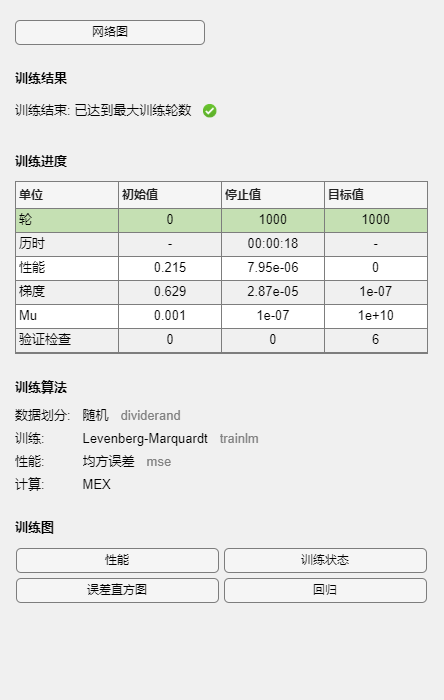

% 模型训练
net = feedforwardnet([8,8]); 
[model_input,model_output] = pre_train(M,real(PA1_input),imag(PA1_input),real(PA1_output),imag(PA1_output),dim);
model = train(net, model_input, model_output);

save('Method_C\PA1\FNN.mat', 'model');

## Model Test

% 系统仿真
Sys_input_DPD=DPD(Sys_input,M,'Method_C\Whole\FNN.mat'); % DPD
[A1_input,A23] = Power_Divider(Sys_input_DPD);
[A2_input,A3_input] = Power_Divider(A23);
A1_input_DPD = DPD(A1_input,M,'Method_C\PA1\FNN.mat'); % DPD
A1_output = PA_1(A1_input_DPD);
A2_input_DPD = DPD(A2_input,M,'Method_C\PA2\FNN.mat'); % DPD
A2_output = PA_2(A2_input_DPD);
A3_input_DPD = DPD(A3_input,M,'Method_C\PA3\FNN.mat'); % DPD
A3_output = PA_3(A3_input_DPD);
Sys_output_sim = Power_Combiner(A1_output,A2_output,A3_output);
% 性能评估
nmse_sim= NMSE_dB(Sys_input,Sys_output_sim);
nmse_1 = NMSE_dB(A1_input,A1_output)

nmse_1 = -37.8368

nmse_2 = NMSE_dB(A2_input,A2_output)

nmse_2 = -38.8643

nmse_3 = NMSE_dB(A3_input,A3_output)

nmse_3 = -41.5376

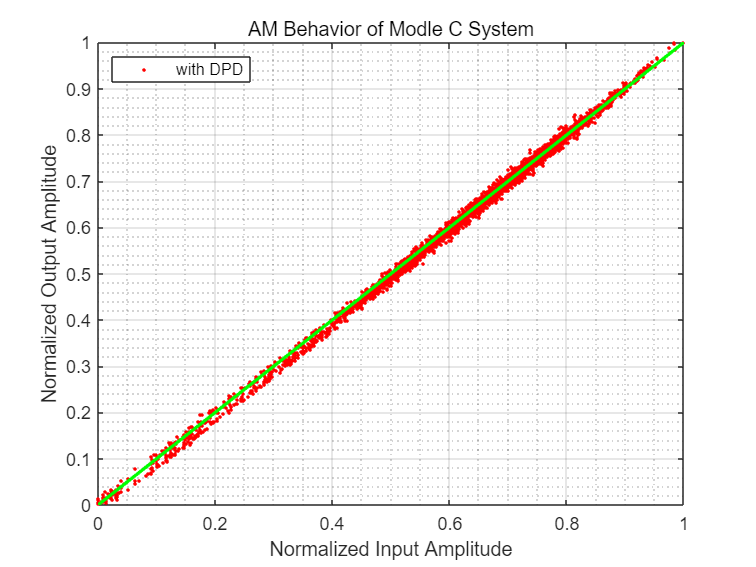

Plot_AM(Sys_input,Sys_output_sim,'AM Behavior of Modle C System','with DPD');

fprintf('使用Model C，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

使用Model C，系统的NMSE仿真结果为 -29.092126 dB


## -----------------------------Model C Valid----------------------------

## 读取数据

clear;
% 读取文件并处理数据
[Data_matrix,dim]=ReadFile_Valid();
% 根据需要选取原始数据
Sys_input = Data_matrix(:,1) + 1i * Data_matrix(:,2); 
% 参数需要保持一致
M = 4;

## Model Test

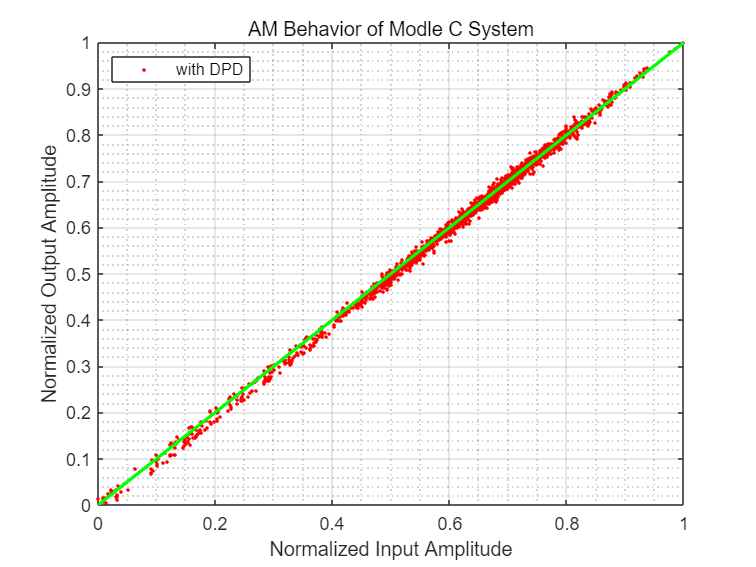

% 系统仿真
Sys_input_DPD=DPD(Sys_input,M,'Method_C\Whole\FNN.mat'); % DPD
[A1_input,A23] = Power_Divider(Sys_input_DPD);
[A2_input,A3_input] = Power_Divider(A23);
A1_input_DPD = DPD(A1_input,M,'Method_C\PA1\FNN.mat'); % DPD
A2_input_DPD = DPD(A2_input,M,'Method_C\PA2\FNN.mat'); % DPD
A3_input_DPD = DPD(A3_input,M,'Method_C\PA3\FNN.mat'); % DPD
A1_output = PA_1(A1_input_DPD);
A2_output = PA_2(A2_input_DPD);
A3_output = PA_3(A3_input_DPD);
Sys_output_sim = Power_Combiner(A1_output,A2_output,A3_output);
% 由于PA和DPD的延时，所以少算（4+2M）个值
Sys_input = Sys_input(5+M*2:end);
Sys_output_sim = Sys_output_sim(5+M*2:end);
% 性能评估
Plot_AM(Sys_input,Sys_output_sim,'AM Behavior of Modle C System','with DPD');

nmse_sim= NMSE_dB(Sys_input,Sys_output_sim);
fprintf('使用Model C，系统的NMSE仿真结果为 %f dB\n', nmse_sim);

使用Model C，系统的NMSE仿真结果为 -29.121842 dB
